% Practice
close all; clear all;

%equations and resulting aug matrix
eq1 = [16 -2 -4 0 -6];
eq2 = [-2 6 0 -2 0];
eq3 = [-4 -2 4 6 0];
eq4 = [0 0 -1 1 -3];
aug_matrix = [eq1 ; eq2 ; eq3 ; eq4];

%analysis
rref(aug_matrix);
rank(aug_matrix);



%equations and resulting aug matrix
vec1 = [16 ; -2 ; -4 ; 0];
vec2 = [-2 ; 6 ; -2 ; 0];
vec3 = [-4 ; 0 ; 4 ; -1];
vec4 = [0 ; -2 ; 6 ; 1];
b = [6 ; 0 ; 0 ; 3];

aug_matrix_vec = [vec1 vec2 vec3 vec4];

%analysis
x1 = aug_matrix_vec \ b;
x2 = inv(aug_matrix_vec)*b;

% Exercise
close all; clear all;

%given data
%Young's Modulus
E_al = 75e+9; %Pa
E_ni = 209e+9; %Pa
E_sa = 197e+9; %Pa
%length
L_ad = 4; %m
L_be = 5; %m
L_cg = 2; %m
%data
P = 90e3; %N
A = 0.0004; %m^2
d = linspace(0, 16, 1600); %m

%QUESTION 1
%Force: Aluminum Alloy 1100 (al)
%matrix
force = [];

for i = 1:length(d)
    eq_1 = [1 1 1 -P];
    eq_2 = [0 10 16 -d(i)*P];
    eq_3 = [6*(L_ad/(E_al*A)) -16*(L_be/(E_al*A)) 10*(L_cg/(E_al*A)) 0];
    aug_matrix_al = [eq_1 ; eq_2 ; eq_3];
    matrix = aug_matrix_al(1:end, 1:end-1);
    b = aug_matrix_al(1:end, end);
    force = [force; transpose(matrix\b)];
end

%Elongation Percentage
perc_al_ad = max((force(:,1))/(E_al*A))*100;
perc_al_be = max((force(:,2))/(E_al*A))*100;
perc_al_cg = max((force(:,3))/(E_al*A))*100;
perc_ni_ad = max((force(:,1))/(E_ni*A))*100;
perc_ni_be = max((force(:,2))/(E_ni*A))*100;
perc_ni_cg = max((force(:,3))/(E_ni*A))*100;
perc_sa_ad = max((force(:,1))/(E_sa*A))*100;
perc_sa_be = max((force(:,2))/(E_sa*A))*100;
perc_sa_cg = max((force(:,3))/(E_sa*A))*100;
perc_al = max([perc_al_ad perc_al_be perc_al_cg])

perc_al = 0.0443

perc_ni = max([perc_ni_ad perc_ni_be perc_ni_cg])

perc_ni = 0.0159

perc_sa = max([perc_sa_ad perc_sa_be perc_sa_cg])

perc_sa = 0.0169




%QUESTION 2
%create F*L matrix
FL = [force(:,1).*(L_ad), force(:,2).*(L_be), force(:,3).*(L_cg)];
FL_diff = [abs(FL(:,3) - FL(:,1))];
FL_diff_min = min(FL_diff);
index = find(FL_diff == FL_diff_min, 1)

index = 1053

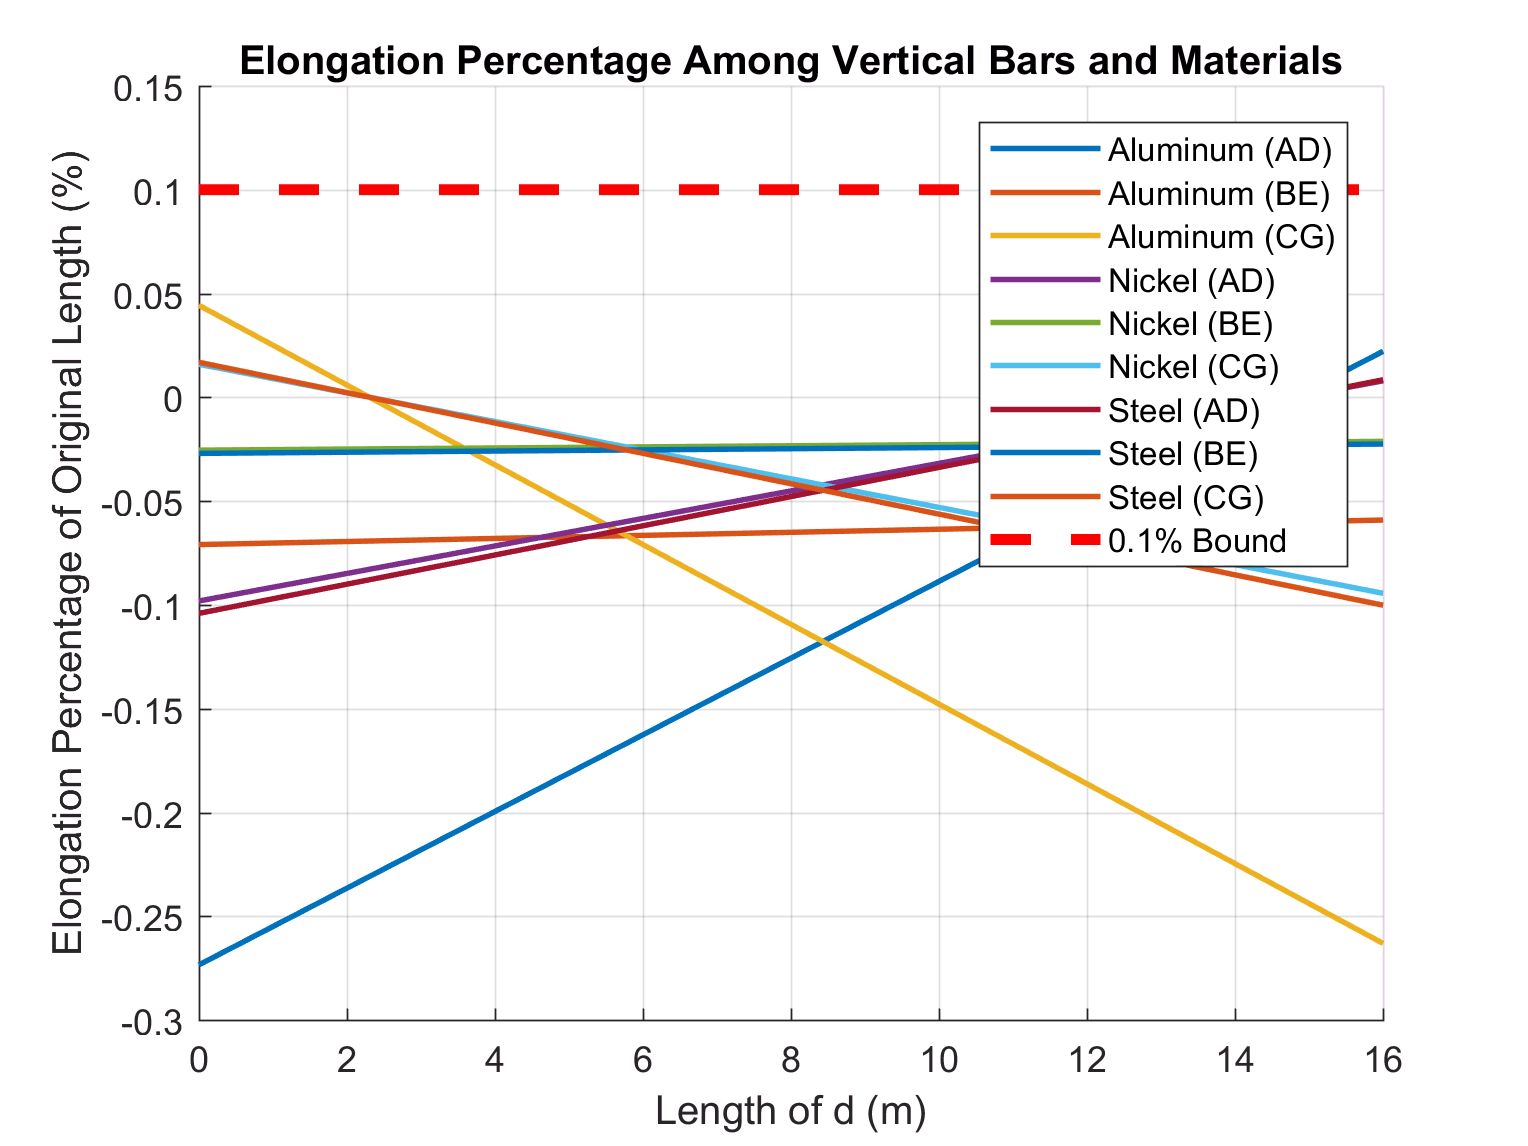



%2 PLOTS
%1) forces on aluminum, nickel, steel alloy
bound = [];
bound(1:length(d)) = 0.1;
hold on;
plot(d, ((force(:,1))/(E_al*A))*100, 'LineWidth', 1.5);
plot(d, ((force(:,2))/(E_al*A))*100, 'LineWidth', 1.5);
plot(d, ((force(:,3))/(E_al*A))*100, 'LineWidth', 1.5);
plot(d, ((force(:,1))/(E_ni*A))*100, 'LineWidth', 1.5);
plot(d, ((force(:,2))/(E_ni*A))*100, 'LineWidth', 1.5);
plot(d, ((force(:,3))/(E_ni*A))*100, 'LineWidth', 1.5);
plot(d, ((force(:,1))/(E_sa*A))*100, 'LineWidth', 1.5);
plot(d, ((force(:,2))/(E_sa*A))*100, 'LineWidth', 1.5);
plot(d, ((force(:,3))/(E_sa*A))*100, 'LineWidth', 1.5);
plot(d, bound, '--r', 'LineWidth', 3);
grid on;
hold off;
title('Elongation Percentage Among Vertical Bars and Materials');
xlabel('Length of d (m)');
ylabel('Elongation Percentage of Original Length (%)');
legend('Aluminum (AD)', 'Aluminum (BE)', 'Aluminum (CG)', 'Nickel (AD)', 'Nickel (BE)', 'Nickel (CG)', 'Steel (AD)', 'Steel (BE)', 'Steel (CG)', '0.1% Bound');

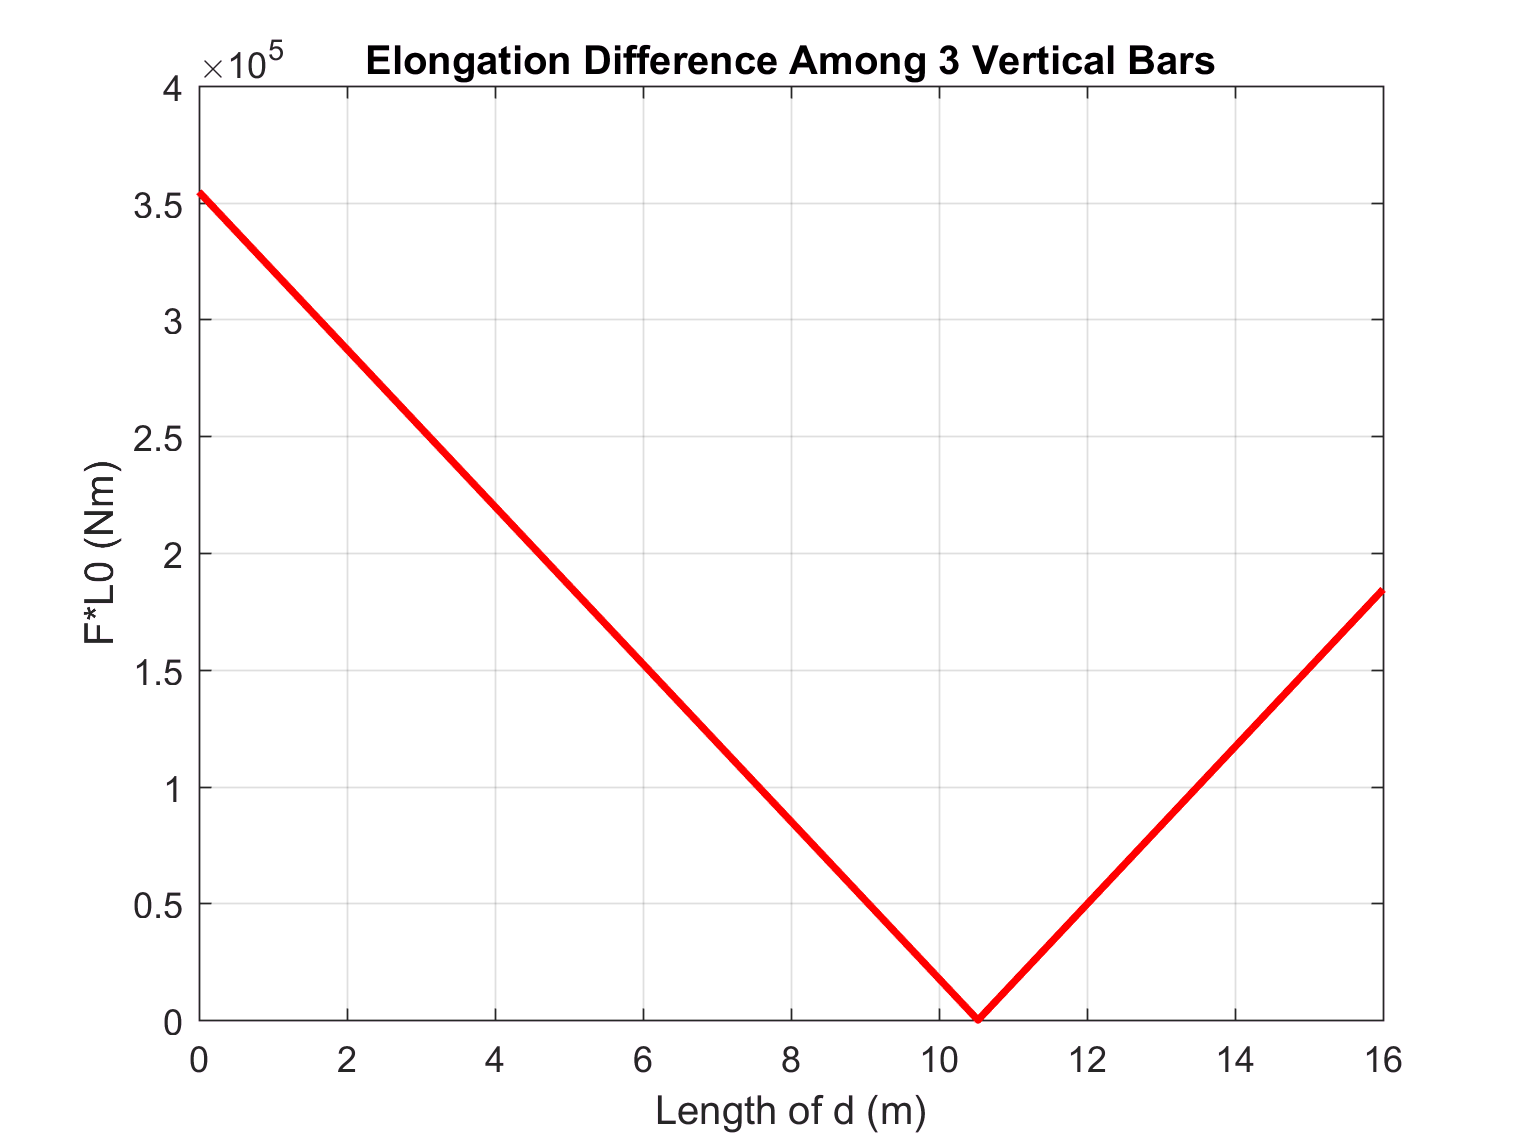


%2) minimum
figure;
plot(d, FL_diff, '-r', 'LineWidth', 2);
grid on;
title('Elongation Difference Among 3 Vertical Bars');
xlabel('Length of d (m)');
ylabel('F*L0 (Nm)');

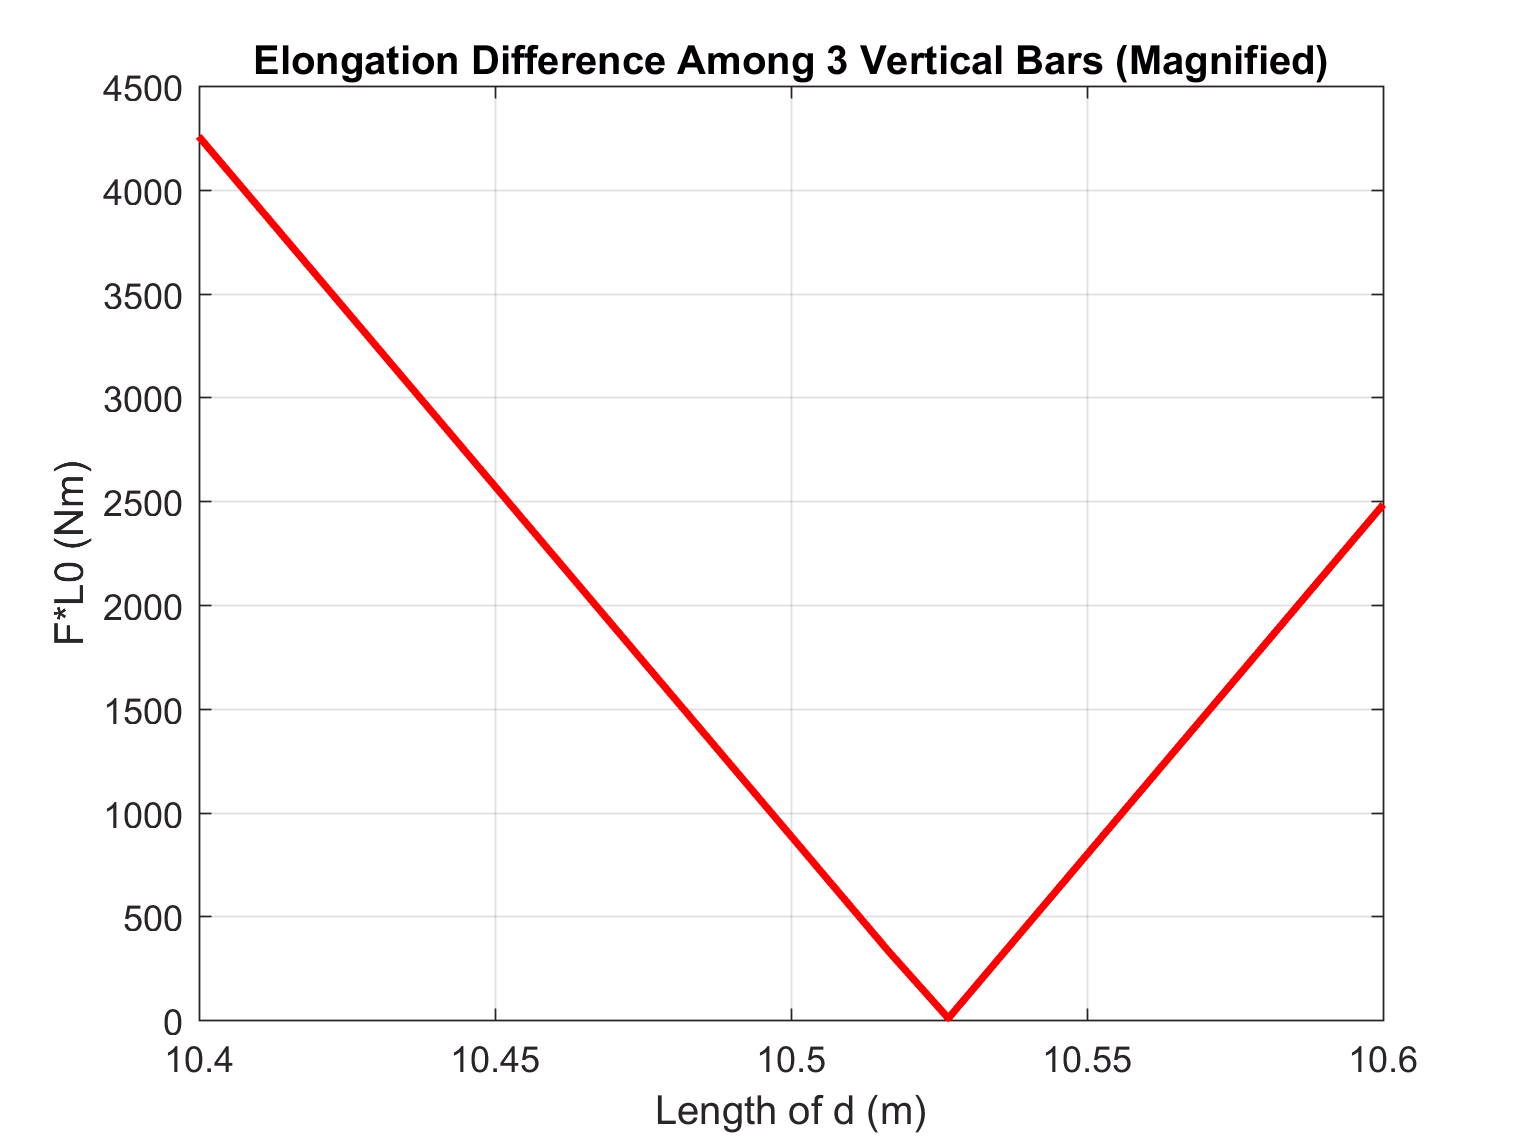


figure;
plot(d, FL_diff, '-r', 'LineWidth', 2);
xlim([10.4 10.6]);
grid on;
title('Elongation Difference Among 3 Vertical Bars (Magnified)');
xlabel('Length of d (m)');
ylabel('F*L0 (Nm)');

    
    
%ANSWERS
%1) While all three materials were able to elongate less than 0.1% of their original length (0 m <= d <= 16 m), the material I would recommend is
%   Aluminum Alloy 1100 due to its lower density and thus, weight.
%2) After comparing the elongation of each of the 3 vertical bars at the entire range of d, d = 10.53 m seems to be where all three bars elongate
%   the same distance and thus, keeping the horizonatal bar leveled.

